# ARO 3090 - Homework 2 - Part 2 (Workout Questions)

## Workout Question 1

clear; clc
% Given
rp_surface = 300; % km from surface of Earth
rE = 6378; % radius of Earth in km
a = rp_surface+rE; % radius @ perigee in km
mu = 398600.4335; % for Earth

### Part a - circular parking orbit

#### Calculate: vp, T, a, e

% Circular orbit so semi-major axis, a = rp = ra
a_parking = a;
% Use vis-viva to calculate velocity at perigee, vp
vp_parking = sqrt( 2*( -mu/(2*a_parking) + (mu/a) ) );
% Calculate orbital period, T
T_parking = 2*pi*sqrt( (a_parking^3)/mu );
% Eccentricity, e = 0 for circular orbit
e_parking = 0;

### Part b - gradual build-up to escape velocity

#### Calculate a, e, T for 4 orbits, building up to escape velocity

vEscape = sqrt(2*mu/a)

vEscape = 10.9260

multiplier = 0.06; % Picked arbitrarily
vp1 = vp_parking + multiplier*vEscape; % New velocity at perigee for 1st deltaV
[a1,e1,T1] = NewOrbit(vp1);
vp2 = vp1 + multiplier*vEscape; % New velocity at perigee for 2nd deltaV
[a2,e2,T2] = NewOrbit(vp2);
vp3 = vp2 + multiplier*vEscape; % New velocity at perigee for 3rd deltaV
[a3, e3, T3] = NewOrbit(vp3);
vp4 = vp3 + multiplier*vEscape; % New velocity at perigee for 4th deltaV
[a4, e4, T4] = NewOrbit(vp4);
vp5 = vEscape; % New velocity at perigee for escape orbit
a5 = Inf; % for parabolic escape trajectory
e5 = 1; % for parabolic escape trajectory
T5 = Inf; % for parabolic escape trajectory


vps = [vp_parking, vp1, vp2, vp3, vp4, vp5]';
as = [a_parking, a1, a2, a3, a4, a5];
es = [e_parking, e1, e2, e3, e4, e5];
Ts = [T_parking, T1, T2, T3, T4, T5];
fprintf("Orbit      Velocity at Perigee (km/s)      Semi-Major Axis (km)       Eccentricity       Period (s)\n------     -----------------------        --------------------        ------------       ----------\nParking         %f                   %f                %f           %f\nEllipse 1       %f                   %f                %f           %f\nEllipse 2       %f                   %f               %f           %f\nEllipse 3       %f                   %f               %f           %f\nEllipse 4       %f                  %f               %f           %f\nEscape          %f                     %f                     %f              %f\n",...
vp_parking,a_parking,e_parking,T_parking,vp1,a1,e1,T1,vp2,a2,e2,T2,vp3,a3,e3,T3,vp4,a4,e4,T4,vp5,a5,e5,T5);

Orbit      Velocity at Perigee (km/s)      Semi-Major Axis (km)       Eccentricity       Period (s)
------     -----------------------        --------------------        ------------       ----------
Parking         7.725839                   6678.000000                0.000000           5431.010058
Ellipse 1       8.381399                   8113.285940                0.176906           7272.875588
Ellipse 2       9.036958                   10569.988865               0.368211           10814.906764
Ellipse 3       9.692517                   15672.998354               0.573917           19527.161449
Ellipse 4       10.348076                  32421.018423               0.794023           58096.633129
Escape          10.925987                     Inf                     1.000000              Inf


## Workout Question 2 - Plotting

mu2 = 62.4; % for given mass
e1 = 0;
e2 = 0.2;
e3 = 0.5;
e4 = 0.7;
e5 = 0.9;
T = 22*3600; % seconds
a = (mu2*(T/(2*pi))^2)^(1/3); % Same for all

fprintf("The semi-major axis is %f km for all orbits",a)

The semi-major axis is 2148.284222 km for all orbits

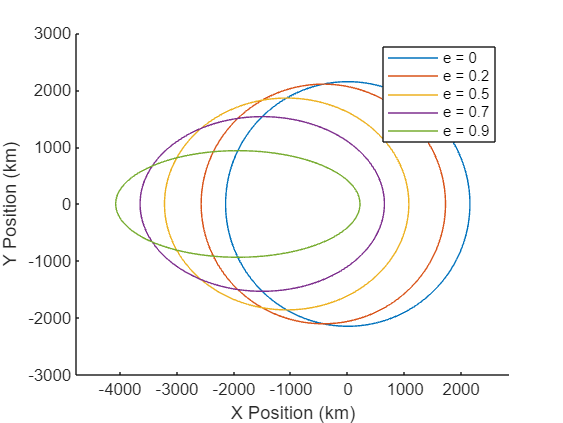



% Assume all spacecraft have the same perigee position
theta = 0:1:360; % degrees
r_theta1=(a.*(1-e1.^2))./(1+(e1.*cosd(theta)));
r_theta2=(a.*(1-e2.^2))./(1+(e2.*cosd(theta)));
r_theta3=(a.*(1-e3.^2))./(1+(e3.*cosd(theta)));
r_theta4=(a.*(1-e4.^2))./(1+(e4.*cosd(theta)));
r_theta5=(a.*(1-e5.^2))./(1+(e5.*cosd(theta)));

for i = 1:length(theta)
    x1(i) = r_theta1(i)*cosd(theta(i));
    y1(i) = r_theta1(i)*sind(theta(i));
    
    x2(i) = r_theta2(i)*cosd(theta(i));
    y2(i) = r_theta2(i)*sind(theta(i));

    x3(i) = r_theta3(i)*cosd(theta(i));
    y3(i) = r_theta3(i)*sind(theta(i));

    x4(i) = r_theta4(i)*cosd(theta(i));
    y4(i) = r_theta4(i)*sind(theta(i));

    x5(i) = r_theta5(i)*cosd(theta(i));
    y5(i) = r_theta5(i)*sind(theta(i));
end


figure
axis padded 
hold on
plot (x1,y1)
xlim([-3000,3000])
ylim([-3000,3000])
% nexttile
plot (x2,y2)
xlim([-3000,3000])
ylim([-3000,3000])
% nexttile
plot (x3,y3)
xlim([-4000,2000])
ylim([-3000,3000])
% nexttile
plot (x4,y4)
% nexttile
plot (x5,y5)
xlim([-3000,3000])
ylim([-3000,3000])
legend("e = 0","e = 0.2","e = 0.5","e = 0.7","e = 0.9")
xlabel("X Position (km)")
ylabel("Y Position (km)")
axis equal
hold off

## Workout Question 3

### Plot true anomaly, eccentric anomaly, and mean anomaly for 3 orbits from Question 1.

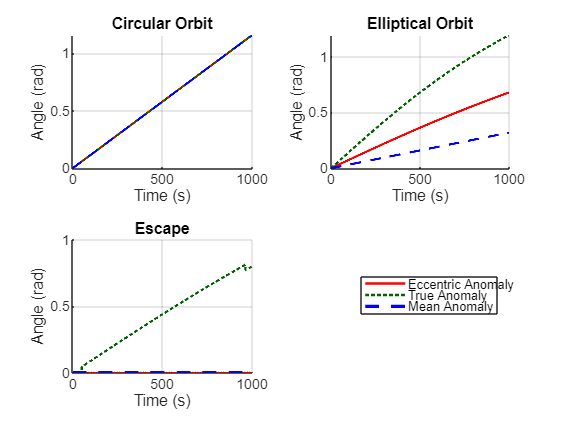

[E_Circle, theta_Circle, M_Circle] = AngleCalculator(6678,0);
[E_Elliptical, theta_Elliptical, M_Elliptical] = AngleCalculator(15763,0.5739); % Orbit #3 from Workout Question 1
[E_Escape, theta_Escape, M_Escape] = AngleCalculator(99999999999,0.9999999); % a~=inf and e~=1
E_Escape = E_Escape;
theta_Escape = theta_Escape;
M_Escape = M_Escape;

figure
tiledlayout(2,2)
nexttile
hold on
plot(E_Circle,"Color","r","LineWidth",1.5)
plot(theta_Circle,"Color","#006400","LineStyle",":","LineWidth",1.5)
plot(M_Circle,"Color","b","LineStyle","--","LineWidth",1.5)
title("Circular Orbit")
hold off
xlabel("Time (s)")
ylabel("Angle (rad)")
grid on

nexttile
hold on
plot(E_Elliptical,"Color","r","LineWidth",1.5)
plot(theta_Elliptical,"Color","#006400","LineStyle",":","LineWidth",1.5)
plot(M_Elliptical,"Color","b","LineStyle","--","LineWidth",1.5)
title("Elliptical Orbit")
hold off
xlabel("Time (s)")
ylabel("Angle (rad)")
grid on

nexttile
hold on
plot(E_Escape,"Color","r","LineWidth",1.5)
plot(theta_Escape,"Color","#006400","LineStyle",":","LineWidth",1.5)
plot(M_Escape,"Color","b","LineStyle","--","LineWidth",2)
title("Escape")
hold off
legend("Eccentric Anomaly","True Anomaly","Mean Anomaly")
xlabel("Time (s)") 
ylabel("Angle (rad)")
grid on

nexttile(3)
legend(["Eccentric Anomaly", "True Anomaly", "Mean Anomaly"], "Position", [0.6417 0.2578 0.2429, 0.0905])


% nexttile
% hold on
% plot(theta_Circle,M_Circle,"Color","r")
% plot(theta_Elliptical,M_Elliptical,"Color","m")
% scatter(theta_Escape,M_Escape,"Color","g")
% xlim([0,2*pi])
% ylim([0,2*pi])
% hold off

function [a e T] = NewOrbit(vp)
    
    % Given
    rp = 6678; % radius @ perigee in km
    mu = 398600.4335; % for Earth    
    
    % Calculate a using vis-viva
    LHS = ((vp^2)/2) - (mu/rp);
    a = -mu/(2*LHS);

    % Calculate e from ra and rp
    ra = 2*a - rp;
    e = (ra-rp)/(ra+rp);

    % Calculate T
    T = 2*pi*sqrt( (a^3)/mu );

end




function [EArray, thetaArray, MArray] = AngleCalculator(a,e)

    tolerance = 0.00001; 
    mu = 398600.435; % for Earth

    for t = 1:1000
        % Calculate Mean anomaly
        MArray(t) = sqrt(mu/(a^3))*t;
    
        % Newton's Method to Calculate Eccentric anomaly
        E(1) = MArray(t);
        f = @(E) E-e.*sin(E)-MArray(t);
        fprime = @(E) 1-e.*cos(E);
        
        for i=1:20
            E(i+1) = E(i) - (f(E(i))/fprime(E(i)));
            error(i) = abs(E(i)-E(i+1));
            if error(i)<tolerance
                break
            end
        end
        numIterations = i;
        EArray(t) = E(i);

        % Calculate True anomaly
        root = sqrt( (1+e)/(1-e) );
        thetaArray(t) = 2*atan(root*tan(EArray(t)/2));

    end

end